### 导入数据集

Train = readtable('E:\研究生学习\模式识别\数据\titanic\train.csv');
Test = readtable('E:\研究生学习\模式识别\数据\titanic\test.csv');
% 看看前五行
head(Train)

ans = 8×12 table
    PassengerId    Survived    Pclass                            Name                               Sex       Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ________    ___    _____    _____    __________________    ______    ______    ________

         1            0          3       'Braund, Mr. Owen Harris'                                'male'       22      1        0      'A/5 21171'             7.25    ''          'S'   
         2            1          1       'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'    'female'     38      1        0      'PC 17599'            71.283    'C85'       'C'   
         3            1          3       'Heikkinen, Miss. Laina'                                 'female'     26      0        0      'STON/O2. 3101282'     7.925    ''          'S'   
         4            1          1       'Futrelle, 

head(Test)

ans = 8×11 table
    PassengerId    Pclass                         Name                           Sex       Age     SibSp    Parch     Ticket       Fare     Cabin    Embarked
    ___________    ______    ______________________________________________    ________    ____    _____    _____    _________    ______    _____    ________

        892          3       'Kelly, Mr. James'                                'male'      34.5      0        0      '330911'     7.8292     ''        'Q'   
        893          3       'Wilkes, Mrs. James (Ellen Needs)'                'female'      47      1        0      '363272'          7     ''        'S'   
        894          2       'Myles, Mr. Thomas Francis'                       'male'        62      0        0      '240276'     9.6875     ''        'Q'   
        895          3       'Wirz, Mr. Albert'                                'male'        27      0        0      '315154'     8.6625     ''        'S'   
        896          3       'Hirv

### 以性别统计存活率

disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'));

                Sex       GroupCount    mean_Survived
              ________    __________    _____________

    male      'male'         577           0.18891   
    female    'female'       314           0.74204   



### 处理数据集中的空值

Feat = Train.Properties.VariableNames   % 提取训练集的特征

Feat = 1×12 cell 数组
    {'PassengerId'}    {'Survived'}    {'Pclass'}    {'Name'}    {'Sex'}    {'Age'}    {'SibSp'}    {'Parch'}    {'Ticket'}    {'Fare'}    {'Cabin'}    {'Embarked'}


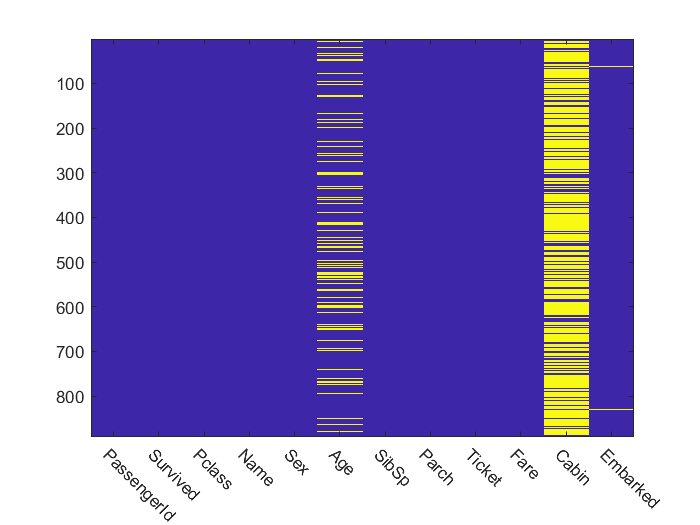

figure
imagesc(ismissing(Train));      % 以颜色的方式展示缺失的值在图像上
set(gca,'XTick',1:12,'XTickLabel',Feat);    % Xtick代表x轴上的标记，XtickLabel即x轴上的标签名
xtickangle(-45)

% 使用平均年龄填补缺失的年龄
avgAge = nanmean(Train.Age);
Train.Age(isnan(Train.Age)) = avgAge;
Test.Age(isnan(Test.Age)) = avgAge;


% 根据Pclass的级别的船费均值来填补Fare
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % 取Pclass与Fare来组合，计算每个Pclass的均值Fare
% 先将Fare里的0转换成NaN
Train.Fare(Train.Fare == 0) = NaN;
Test.Fare(Test.Fare == 0) = NaN;
% 对Fare的空值进行填补
for i=1:height(fare)
    Train.Fare(Train.Pclass == i&isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i&isnan(Test.Fare)) = fare.mean_Fare(i);
end

%% 对数据的Cabin进行处理
% 提取Cabin，若有多个Cabin则以元胞数组形式
Train_cabins = cellfun(@strsplit,Train.Cabin,'UniformOutput',false);    % 非标量时需设置UniformOutput,false
Test_cabins = cellfun(@strsplit,Test.Cabin,'UniformOutput',false);
% 计算每个人的舱位数
Train.nCabins = cellfun(@length,Train_cabins);
Test.nCabins = cellfun(@length,Test_cabins);
% 处理异常数据(只有级别为1的乘客拥有多个舱位)
Train.nCabins(Train.Pclass ~= 1&Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1&Test.nCabins > 1,:) = 1;
% 没有舱位的定义为0
Train.nCabins(ismissing(Train.Cabin)) = 0;
Test.nCabins(ismissing(Test.Cabin)) = 0;

disp(grpstats(Train(:,{'Survived','Embarked'}),'Embarked'));

         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    S      'S'          644           0.33696   
    C      'C'          168           0.55357   
    Q      'Q'           77           0.38961   



% 用存活率最低的S来填补缺失的港口值
for i = 1:891
    if isempty(Train.Embarked{i})
        Train.Embarked{i} = 'S';
    end
end
for i = 1:418
    if isempty(Test.Embarked{i})
        Test.Embarked{i} = 'S';
    end
end
% 将港口名转换成double类型
Train.Embarked = double(cell2mat(Train.Embarked));
Test.Embarked = double(cell2mat(Test.Embarked));


% 将性别也转换成double类型的1和0
cmp1 = strcmp(Train.Sex,'male');
Train.Sex(cmp1) = num2cell(1);
Train.Sex(~cmp1) = num2cell(0);
cmp2 = strcmp(Test.Sex,'male');
Test.Sex(cmp2) = num2cell(1);
Test.Sex(~cmp2) = num2cell(0);
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);
% 删掉不用的列
Train(:,{'Name','Ticket','Cabin'}) = [];
Test(:,{'Name','Ticket','Cabin'}) = [];

### 使用朴素贝叶斯进行预测

% 将数据分为训练集和测试集
data = Train.Variables;
x = (data(:,3:10))';
gnd = data(:,2);
X_Train = x(:,1:end);
gnd_Train = (gnd(1:end))';
%X_Test = x(:,701:end);
%gnd_Test = (gnd(701:end))';

[pp, temp0, temp1,t_mean,t_std] = NB(X_Train,gnd_Train);
% 统计pclass每个级别的存活率及死亡率
for i = 1:3
    p_pclass0(i) = grpstats(temp0(1,:)==i);
    p_pclass1(i) = grpstats(temp1(1,:)==i);
end
% 统计男女的存活率及死亡率
for i = 1:2
    p_sex0(i) = grpstats(temp0(2,:)==(i-1));
    p_sex1(i) = grpstats(temp1(2,:)==(i-1));
end
%[post_p,test_lab] = predict(X_Test,pp, 2,6, t_mean, t_std,p_pclass0,p_pclass1,p_sex0,p_sex1);

% 将数据提取出来
data = Test.Variables;
Test_x = (data(:,2:9))';

[post_p0,test_lab0] = predict(Test_x,pp, 2,6, t_mean, t_std,p_pclass0,p_pclass1,p_sex0,p_sex1);
submission = Train(1:418,1:2);
submission(:,'PassengerId') = Test(:,'PassengerId');
submission(:,'Survived') = num2cell(test_lab0');
writetable(submission,'E:\submission.csv');

### NB

function [pp, temp0, temp1,t_mean,t_std] = NB(data,label)
% 计算先验概率
lab = unique(label);
labClass = length(lab);
    for i = 1:labClass
        % pp存放先验概率
        pp(i) = sum(label==lab(i));
        pp(i) = pp(i)/length(label);
    end
% 
[row,~] = size(data);

for i = 1:row
    %for j = 1:labClass
        temp0(i,:) = data(i, label==lab(1));
        temp1(i,:) = data(i, label==lab(2));
    if i > 2
        t_mean(i-2,1) = mean(temp0(i,:));
        t_mean(i-2,2) = mean(temp1(i,:));
        t_std(i-2,1) = std(temp0(i,:));
        t_std(i-2,2) = std(temp1(i,:));
        
   end
end

end

function [post_p,test_lab] = predict(test,pp, labClass, vars,t_mean,t_std,p_pclass0,p_pclass1,p_sex0,p_sex1)
[~,len] = size(test);    % 预测多少次
for k = 1:len
    temp = test(:,k);
    for i = 1:labClass
        prod = 1;
        if i == 1   % 计算死亡概率
            t_pclass = temp(1);
            t_sex = temp(2)+1;
            prod = prod*p_pclass0(t_pclass)*p_sex0(t_sex);
            for j = 1:vars
                prod=prod*mvnpdf(temp(j+2),t_mean(j,i),t_std(j,i));
            end
        else    % 计算存活概率
            prod = prod*p_pclass1(t_pclass)*p_sex1(t_sex);
            for j = 1:vars
                prod=prod*mvnpdf(temp(j+2),t_mean(j,i),t_std(j,i));
            end
        end
    post_p(k,i)=prod*pp(i);
    end
    [~,inx] = max(post_p(k,:));
    test_lab(k) = inx-1;
end

end